# EE208 Experiment-1 

# Dynamic response of transfer functions on MATLAB platform.

## Objective

We shall analyze and discuss the dynamic response of a given linear analog system in terms of different performance measures with MATLAB. 

## Topics Covered

- Step Responses

- Effect of zeros on Step Response

- Cascade and Feedback Connections

- Effect of OLTF gain

- Step Response performance measures

## Project Statement

You are given the second order analog OLTF of an oven temperature system is provided, for which a given PD controller is to be considered in (a) Cascade and (b) Feedback.

**OLTF : **$\frac{K}{s^2 +3s+10}$

**PD Controller : **$80\left(s+5\right)$

In either configuration, the CL root loci are identical. However the step response always differs. Compare the two responses in terms of standard performance measures to a step input, comment on the results, and explain the reason for the differences in the response. 

If the OL gain of the oven temperature OLTF is prone to variation, investigate the effect of this on the performance measures, and explain the reason for the same. 

## MATLAB Functions Used

The following functions were used :

- tf

- feedback

- step

- stepinfo

- pzmap

- grid

- ones

- zeros

- stepplot

- table

- length

- residue

- linspace

- logspace

## MATLAB Code Setup

Let us first create the OLTF and the PD controller for K=1.

clear;
s = tf('s'); %creating an empty TF to be used as a variable.
G = 1/(s^2 + 3*s +10); %creating the OLTF with K=1.
C = 80*(s+5); %creating the PD Controller

Since MATLAB cannot handle variables in transfer functions, we shall create an array of K-values.

K = [0.01, 0.1, 0.5, 1, 2, 4, 10,];

Next we shall create a model array for the OLTF.

system = tf(zeros(1,1,1,length(K)));
for i = 1:length(K)
    system(:,:,:,i) = G*K(i);
end

Now, we create the Cascaded and Feedback CLTF arrays.

cltf_cascade = feedback(C*system,1);
cltf_fdback = feedback(system,C);

We'll also create the CLTFs for K=1 separately for easy analysis. 

cltf_cascade_1 = feedback(G*C,1);
cltf_fdback_1 = feedback(G,C);

We are now ready to perform the step response analyses.

## Observations and Discussion

We shall now observe the step responses of the two CLTFs, compare the performance measures, explain the step responses, and discuss the effect of variable OLTF gain. 

Initially we shall work with K=1, and then we shall observe the effect of changing K. 

### Visualising the Step responses

The step response can be obtained by the step() function.

*Step Response for OLTF*

h = stepplot(G);
grid on
h.showCharacteristic('SteadyState')
h.showCharacteristic('SettlingTime')
h.showCharacteristic('PeakResponse')
h.showCharacteristic('RiseTime')

*Step Response for Cascade CLTF*

h = stepplot(cltf_cascade_1);
grid on
h.showCharacteristic('SteadyState')
h.showCharacteristic('SettlingTime')
h.showCharacteristic('PeakResponse')
h.showCharacteristic('RiseTime')

*Step Response for Feedback CLTF*

h = stepplot(cltf_fdback_1);
grid on
h.showCharacteristic('SteadyState')
h.showCharacteristic('SettlingTime')
h.showCharacteristic('PeakResponse')
h.showCharacteristic('RiseTime')

*Viewing all the responses together*

step(G,'r',cltf_cascade_1,'b',cltf_fdback_1,'g',5), grid

The response for cltf_fdback_1 is quite small, so it is seen only as a green line at the bottom.

### Comparing Performance Measures

Response = ["OLTF";"Cascade CLTF";"Feedback CLTF"];
SteadyStateError = 1-[0.1;0.976;0.00244]; %Ess
PeakTime = [1.14;0.077;0]; %Tpeak
PeakOvershoot = [18.4;3.66;0]; %Mp
SettlingTime = [2.61;0.205;0.755]; %Tsettling
RiseTime = [0.503;0.0237;0.418]; %Trise
Data = table(Response, SteadyStateError, PeakTime, PeakOvershoot, SettlingTime, RiseTime)

We can clearly see that the Cascade CLTF has the fastest response of the three - it rises and settles very swiftly. It has a large, quickly decaying overshoot, which does not oscillate. It also has the smallest steady-state error. The PD Controller seems to be working well for the step input. 

The OLTF shows oscillatory dynamics. It rises slowly and has the greatest settling time. It has a large steady-state error, rising only to 0.1 units in the steady-state.

The Feedback CLTF displays slow,lag type dynamics and rises to a very small steady state value, and thus has the largest steady state error. It appears that this configuration is not useful if our purpose is to closely follow the reference signal. 

### Explaining the Step Responses

There is a great difference in the responses of the Cascade CLTF and the Feedback CLTF. To understand the reason for the difference, we must first have a look at the CLTFs themselves.

cltf_fdback_1

cltf_fdback_1 =
 
         1
  ----------------
  s^2 + 83 s + 410
 
Continuous-time transfer function.



This is the CLTF for the controller in feedback. It is a simple 2nd order TF, whose poles can be found as follows :

pole(cltf_fdback_1)

ans =   -77.7250
   -5.2750


Thus it has poles at -77.725 and -5.275.

Now we look at the CLTF for the controller in cascade.

cltf_cascade_1

cltf_cascade_1 =
 
     80 s + 400
  ----------------
  s^2 + 83 s + 410
 
Continuous-time transfer function.



The denominator is the same as before - thus the poles are the same - but this transfer function has a zero at s=-5. Also, it has a different DC gain, which we shall now normalize for ease of analysis.

Let us create new variables. We have put the transfer functions in standard form, and have removed the gain of 80 in the cascade CLTF. This will allow us to easily compare the two. 

H_f = tf( 410, [1,83,410])

H_f =
 
        410
  ----------------
  s^2 + 83 s + 410
 
Continuous-time transfer function.



H_c = tf([1/5,1],(1))*H_f

H_c =
 
     82 s + 410
  ----------------
  s^2 + 83 s + 410
 
Continuous-time transfer function.



Now we once again look at the step responses - 

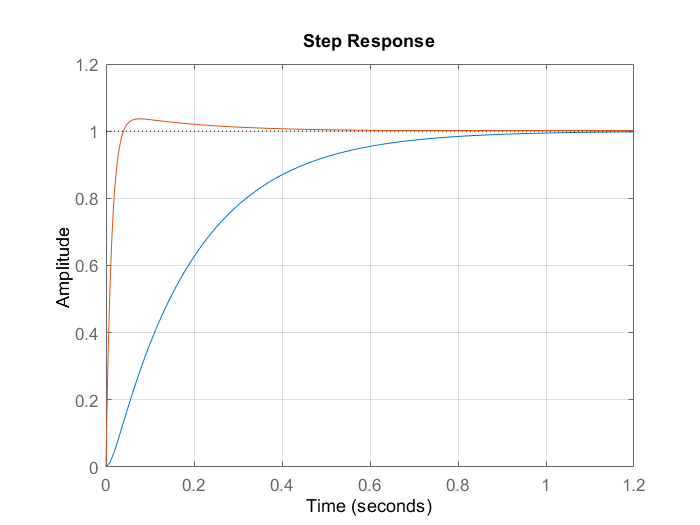

step(H_f,H_c), grid on

It is clear that the addition of a zero "speeds" up the response in some way.

From the transfer functions : 


$$H_c =H_f -\frac{1}{\left(-5\right)}*\left({s\times H}_f \right)$$


We know that s*H_f is simply the derivative of H_f. 

Hence our time response becomes :

#### 
$$\textrm{Cascade}\;\textrm{Step}\;\textrm{Response}=\textrm{Feedback}\;\textrm{Response}-\frac{1}{\left(\textrm{value}\;\textrm{of}\;\textrm{zero}\right)}*\frac{\mathrm{d}}{\mathrm{d}t}\textrm{Feedback}\;\textrm{Response}$$


In other words, the effect of adding a zero to is to add a *scaled version of the derivative of the original response to the orginal response*.

It is this addition of the derivative response that makes the overall response "faster".

Let us plot this. 

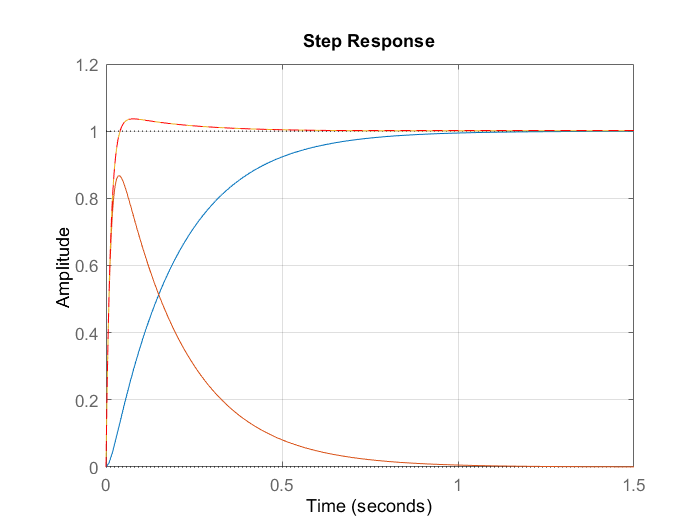

der_H_f = tf([1,0],1) * H_f; %derivative of H_f
step(H_f,der_H_f*0.2,H_f + der_H_f*0.2,H_c,'r--'), grid on

We see that H_c lines up perfectly with H_f + 0.2*der_H_f.

Thus we have explained the reason for difference between the step responses.

Let us now look at the unnormalized transfer functions,still with gain of 80 removed for the sake of visualization - although it makes no difference to the dynamics, as we shall see. 

T_f = tf( 1, [1,83,410])

T_f =
 
         1
  ----------------
  s^2 + 83 s + 410
 
Continuous-time transfer function.



T_c = tf([1,5],(1))*T_f

T_c =
 
       s + 5
  ----------------
  s^2 + 83 s + 410
 
Continuous-time transfer function.



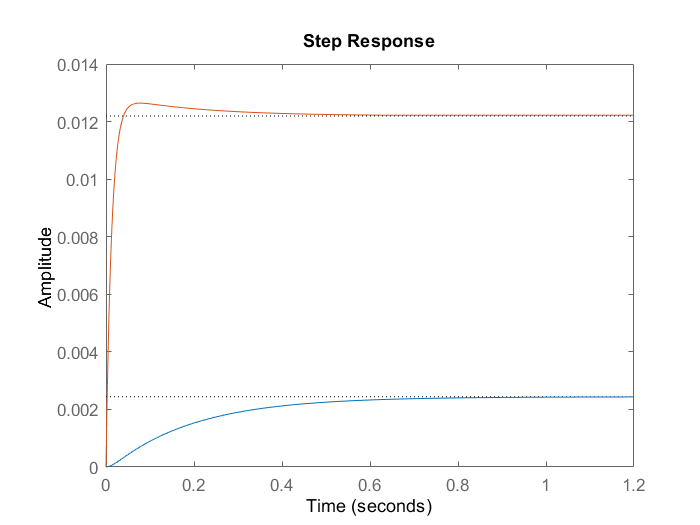

step(T_f,T_c)

stepinfo(H_c)

ans = struct with fields:
        RiseTime: 0.0237
    SettlingTime: 0.2051
     SettlingMin: 0.9054
     SettlingMax: 1.0366
       Overshoot: 3.6644
      Undershoot: 0
            Peak: 1.0366
        PeakTime: 0.0770


stepinfo(T_c)

ans = struct with fields:
        RiseTime: 0.0237
    SettlingTime: 0.2051
     SettlingMin: 0.0110
     SettlingMax: 0.0126
       Overshoot: 3.6644
      Undershoot: 0
            Peak: 0.0126
        PeakTime: 0.0770


 Clearly the only effect is the increase in DC gain - i.e. effect on Peak. The overall dynamics remain the same.

### Effect of position of the zero on the Step response

Let us plot various step responses corresponding to different placements of the zero. 

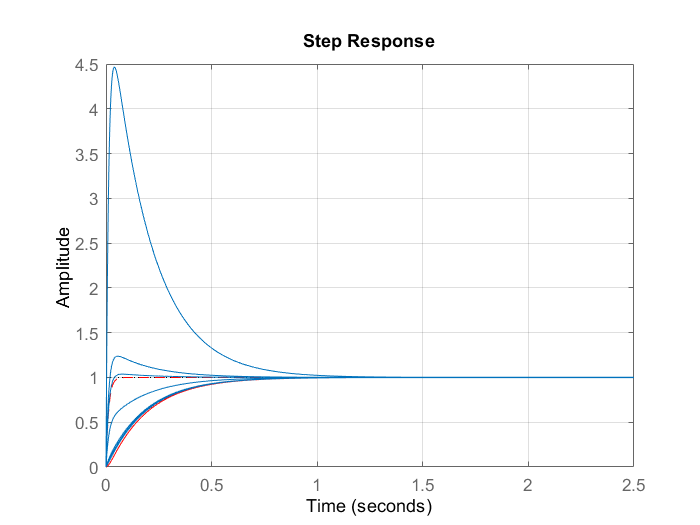

Zeros = [1,4,5,10,50,70,100];
sys1 = tf(zeros(1,1,1,length(Zeros)));
for i = 1:length(Zeros)
    sys1(:,:,:,i) = tf([1/Zeros(i),1],(1))*H_f;
end
step(H_f, 'r', H_f*tf([1/5.275,1],(1)), 'r--', H_f*tf([1/77.725,1],1), 'r--', sys1), grid on

There are many things to observe :

- The overshoot tends to infinity as we approach the origin, this is because in our scaling we have divided by the zero. 

- For zeros smaller than the first pole, we have an early overshoot that decays quickly. In this region, the dynamics of the larger pole dominate since those of the smaller pole are, to an extent, dulled out by the effect of the zero.

- As we reach Pole 1, there is cancellation, and so we obtain a 1st order TF. The step response of this TF is that of exponential growth, with a small time constant befitting the large magnitude of Pole 2 (-77.725).

- Between Poles 1 and 2 - there are no overshoots now, and the dynamics are lag type, with characteristics in-between those at Pole 1 and Pole 2.

- Once again, when we approach Pole 2, cancellation occurs and we are once again left with the step response corresponding to the the 1st order low-pass TF at frequency 5 rad/s. Since it was the high-magnitude pople which was cancelled this time, the dynamics are slow.

- Beyond Pole 2, we begin to approach the original, zero-less curve, which corresponds to a zero at infinity. 

What happens upon denormalization?

sys2 = tf(zeros(1,1,length(Zeros)));
for i = 1:length(Zeros)
    sys2(:,:,:,i) = tf([1,Zeros(i)],(1))*H_f/410;
end
step(H_f/410, 'b', H_f*tf([1,5.275],(1))/410, 'r--', H_f*tf([1,77.725],1)/410, 'r--', sys2), grid on

The dynamics are the same as before, just un-normalized so the larger zeros cause large DC gains, and thus larger steady state values. 

Does this have an effect on the performance measures?

stepinfo(sys1(1,1,1,1))

ans = struct with fields:
        RiseTime: 0.0022
    SettlingTime: 0.7948
     SettlingMin: 1.0025
     SettlingMax: 4.4643
       Overshoot: 346.4319
      Undershoot: 0
            Peak: 4.4643
        PeakTime: 0.0403


stepinfo(sys2(1,1,1,1))

ans = struct with fields:
        RiseTime: 0.0022
    SettlingTime: 0.7948
     SettlingMin: 0.0024
     SettlingMax: 0.0109
       Overshoot: 346.4319
      Undershoot: 0
            Peak: 0.0109
        PeakTime: 0.0403


We see that normalization doesn't effect our performance measures - only the absolute values are changed, dynamics remain the same.

Let us see how our performance measures change as we place zeros at different locations. 

Zeros = linspace(1,90,70);
sys1 = tf(zeros(1,1,1,length(Zeros)));
for i = 1:length(Zeros)
    sys1(:,:,:,i) = tf([1/Zeros(i),1],(1))*H_f;
end


From the denormalized responses above, we can see that steady-state error decreases as we place larger poles. 

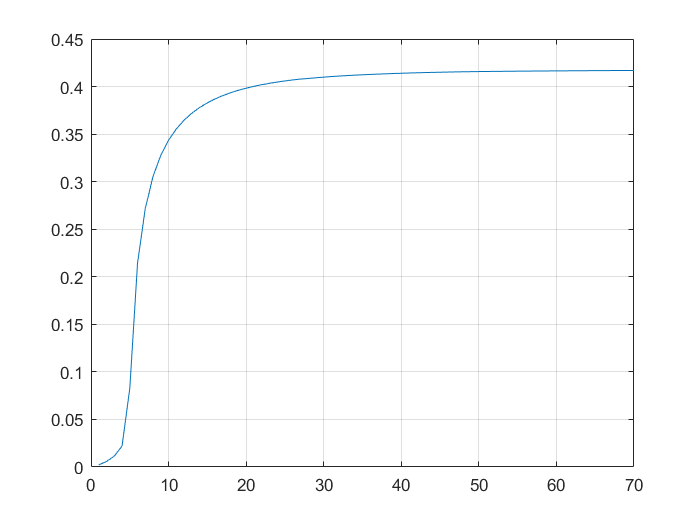

x = zeros(1,length(Zeros));
for i=1:length(Zeros)
    x(:,i) = stepinfo(sys1(:,:,:,i)).RiseTime;
end
plot(x), grid on

Initially we have fast dynamics, that die out as we pass Pole 1. Our RiseTime quickly increases, then slows down beyond z=-10. We approach the RiseTime of H_f as we move our zero towards -infinity. 

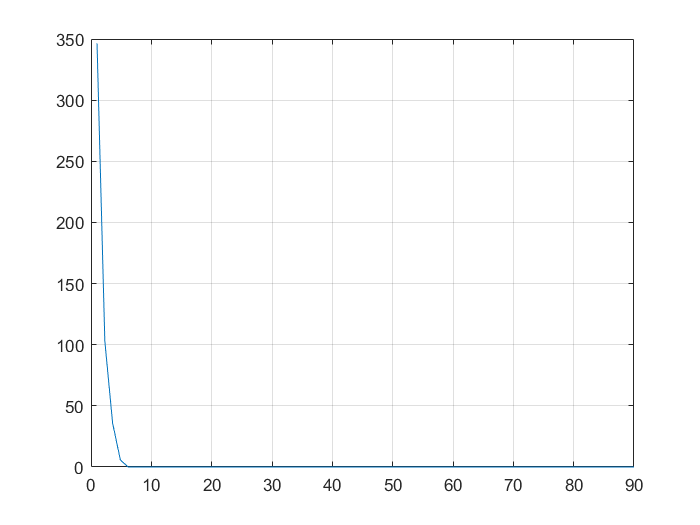

x2 = zeros(1,length(Zeros));
for i=1:length(Zeros)
    x2(:,i) = stepinfo(sys1(:,:,:,i)).Overshoot;
end
plot(Zeros,x2), grid on

The inital zeros cause a large overshoot, which suddenly dies out after we cross Pole 1.

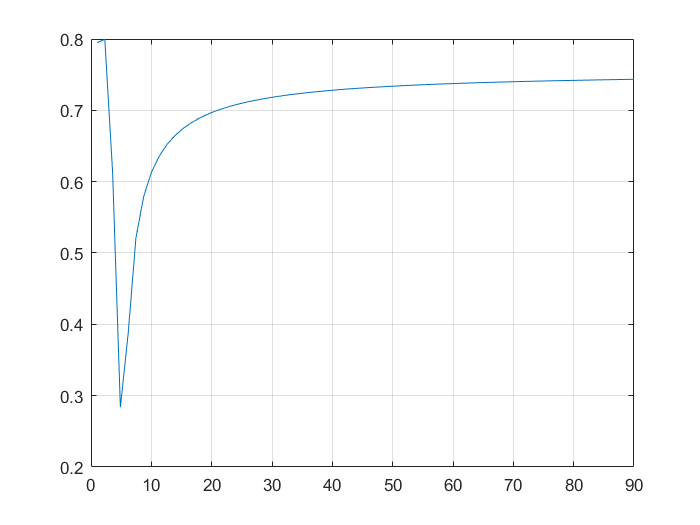

x3 = zeros(1,length(Zeros));
for i=1:length(Zeros)
    x3(:,i) = stepinfo(sys1(:,:,:,i)).SettlingTime;
end
plot(Zeros,x3), grid on

Settling time quickly decreases till we reach Pole 1 - only Pole 2's dynamics exist here, so this is the position of settling time. Beyond Pole 1, settling time keeps increasing - slow dynamics of Pole 1 aren't cancelled as easily by the zero as it moves away from it.   

### Linking the Step Response to the Transfer function with Residues

We shall use the residue-pole-direct term form of the transfer function to see how the zero directly effects the step response.

[r1,p1,k1] = residue(1,[1,83,410,0]);
[r2,p2,k2] = residue([80,400],[1,83,410,0]);

First for the residues and poles of cltf_fdback_1*(1/s). 1/s is the TF for a step input. We can obtain the step response analytically with an Inverse transform.   

r1

r1 =     0.0002
   -0.0026
    0.0024


p1

p1 =   -77.7250
   -5.2750
         0


The decomposed transfer function is thus $\frac{0\ldotp 0002}{s+77\ldotp 725}-\frac{0\ldotp 0026}{s+5\ldotp 275}+\frac{0\ldotp 0024}{s}$. 

In the time domain, this will be $0\ldotp 0002\cdot e^{-77\ldotp 725\cdot t} -0\ldotp 0026\cdot e^{-5\ldotp 275\cdot t} +0\ldotp 0024$. 

Now we look at the residues and poles of cltf_cascade_1*(1/s)

r2

r2 =    -1.0332
    0.0576
    0.9756


p2

p2 =   -77.7250
   -5.2750
         0


The TF is now $\frac{-1\ldotp 0332}{s+77\ldotp 725}+\frac{0\ldotp 0576}{s+5\ldotp 275}+\frac{0\ldotp 9756}{s}$, which in the time domain will be $-1\ldotp 0332\cdot e^{-77\ldotp 725\cdot t} +0\ldotp 0576\cdot e^{-5\ldotp 275\cdot t} +0\ldotp 9756$.

 Let us plot the time domain equations to see how the relative contribution of each mode is changed. 

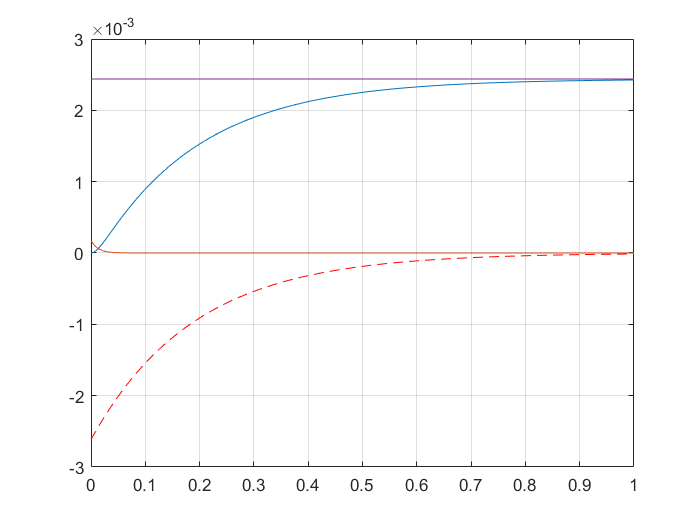

t = linspace(0,1,1000);
y1 = r1(1)*exp(p1(1)*t) + r1(2)*exp(p1(2)*t) + r1(3)*exp(p1(3)*t);
y2 = r2(1)*exp(p2(1)*t) + r2(2)*exp(p2(2)*t) + r2(3)*exp(p2(3)*t);

plot(t,y1,t,r1(1)*exp(p1(1)*t),t,r1(2)*exp(p1(2)*t),'r--',t,r1(3)*exp(p1(3)*t)),grid on

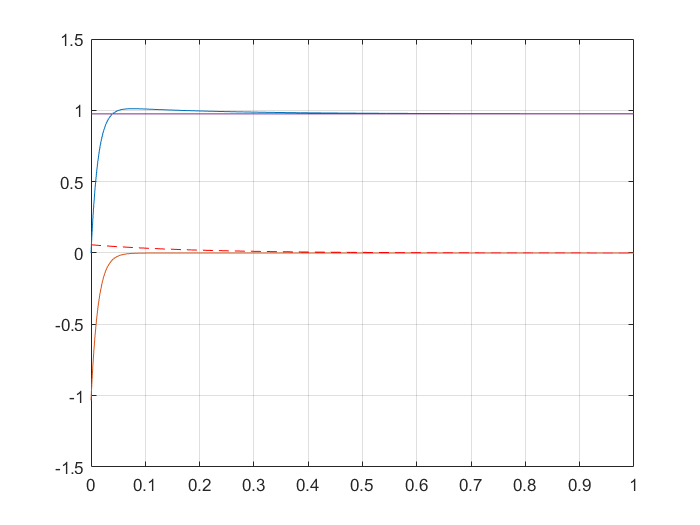

plot(t,y2,t,r2(1)*exp(p2(1)*t),t,r2(2)*exp(p2(2)*t),'r--',t,r2(3)*exp(p2(3)*t)),grid on

From these plots we can clearly see the contribution of each term. Purple is the forced response - a constant curve. Red is the response of the pole at -5.275, and yellow is the response of the pole at -77.725. 

**Because of the addition of the zero, the dominant response is that of Pole 2 (-77.725). The zero cancels the effects of Pole 1 to a large extent. **

The effect of the gain of 80 is only in the overall scaling, it doesn't affect the dynamics. 

### Visualizing the effect of variable OLTF gain "K" 

Let us now look at the effect of variable "K" on the dynamics. We shall look at the Cascade connected CLTF response only, since it makes no difference to the effect of K and is easier to visualise. 

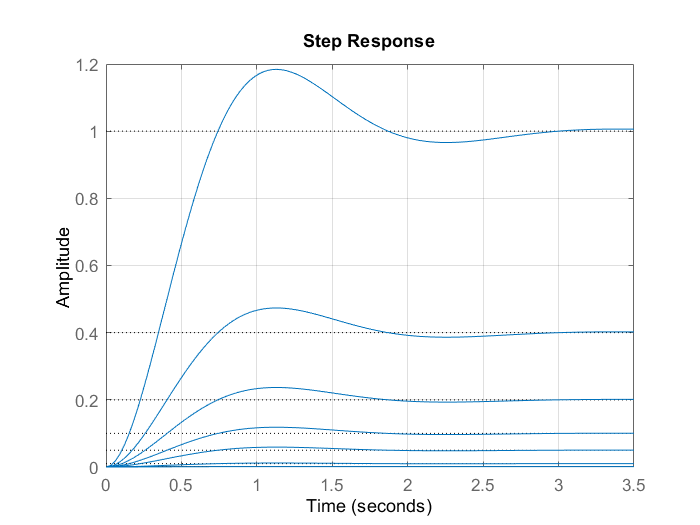

step(system), grid on

For the OLTF, variable K only changes DC gain and steady-state error, and has no effect on the dynamics as such. 

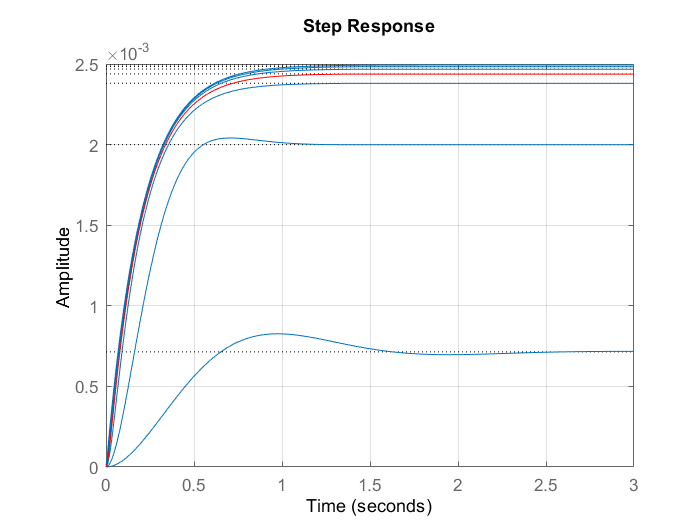

step(cltf_fdback,cltf_fdback_1,'r'), grid on

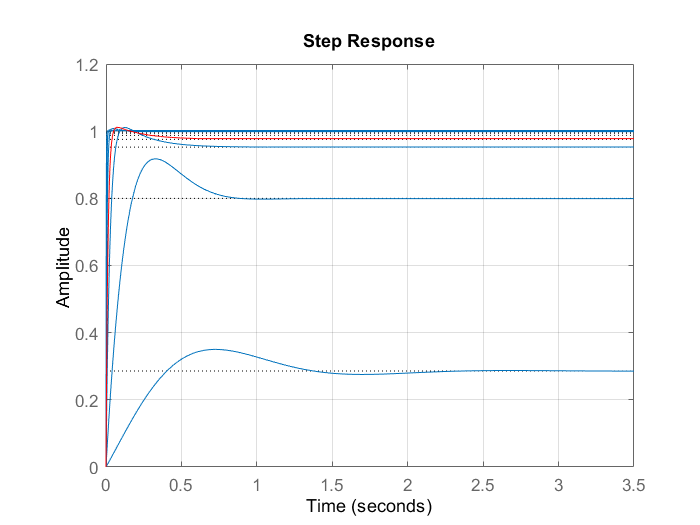

step(cltf_cascade,cltf_cascade_1,'r'), grid on

Clearly, variable K can change the dynamics of the CLTF! 

What happens when we  "vibrate" K around a certain value, say K=1?

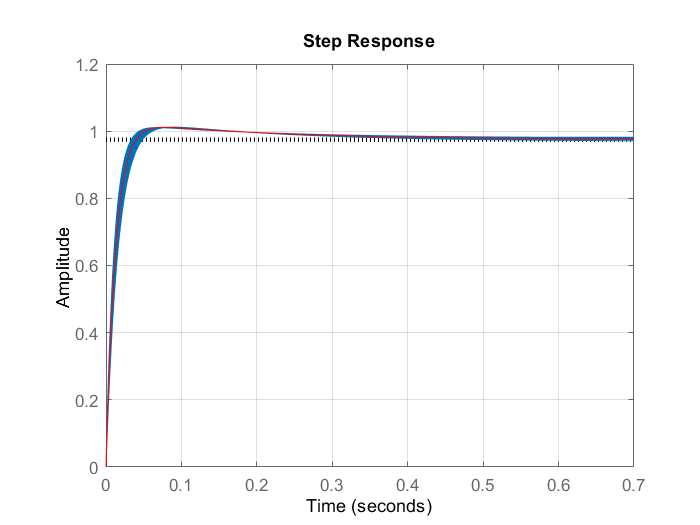

K2 = linspace(0.8,1.2,20);
system2 = tf(zeros(1,1,1,length(K2)));
for i = 1:length(K2)
    system2(:,:,:,i) = G*K2(i);
end
cltf_cascade2 = feedback(C*system2,1);

step(cltf_cascade2,cltf_cascade_1,'r'), grid on

It looks like the dynamics don't change greatly around K=1. Let us look around K=0.01.

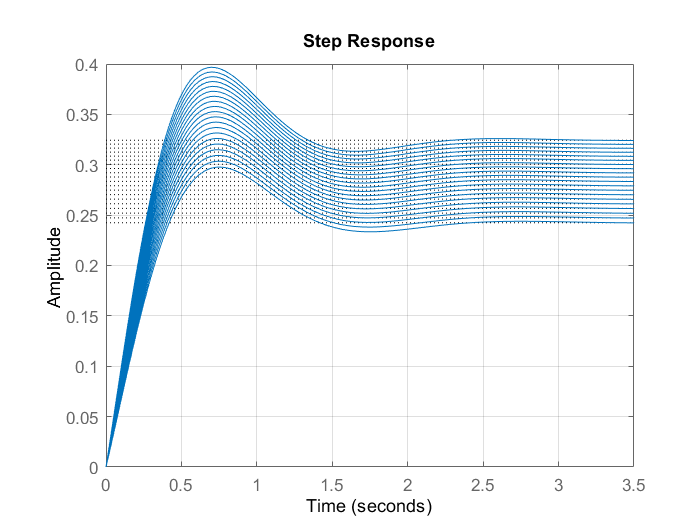

K3 = linspace(0.008,0.012,20);
system3 = tf(zeros(1,1,1,length(K3)));
for i = 1:length(K3)
    system3(:,:,:,i) = G*K3(i);
end
cltf_cascade3 = feedback(C*system3,1);

step(cltf_cascade3), grid on

Around K=0.1, the effect of changing K is much more prominent, although the response still remains oscillatory. 

### Explaining the effect of variable K

To understand *how* K affects the dynamics, we shall look at the transfer functions. 

Let us look at cltf_cascade's pole-zero map, so we can see at the zero too - 

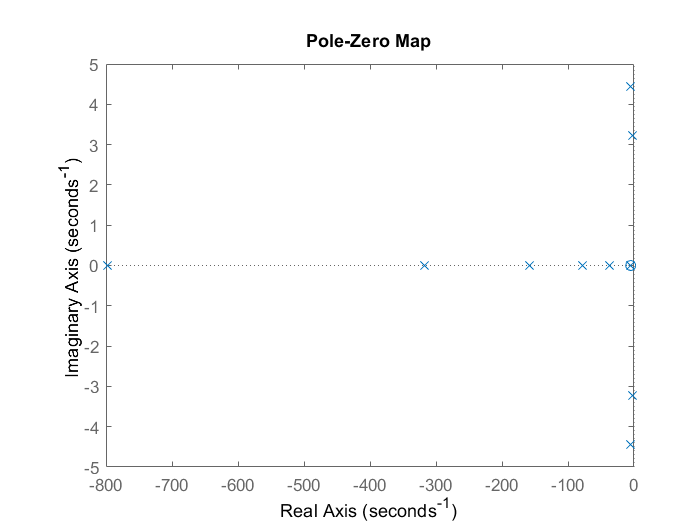

pzmap(cltf_cascade)

We can see that the zero remains unaffected by variable K, while the poles are changed - this is what causes the change in dynamics. This is, in effect, what is called the "Root Locus" - that explains how K changes the poles of the system.

Let us see how the performance measures are affected. 

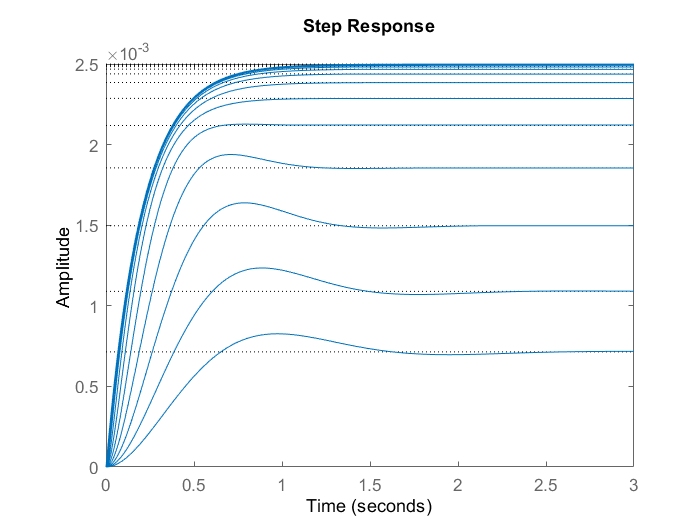

K4 = logspace(-2,2,15);
system4 = tf(zeros(1,1,1,length(K4)));
for i = 1:length(K4)
    system4(:,:,:,i) = G*K4(i);
end
cltf_cascade4 = feedback(C*system4,1);
cltf_fdbackk = feedback(system4,C);
step(cltf_fdbackk)

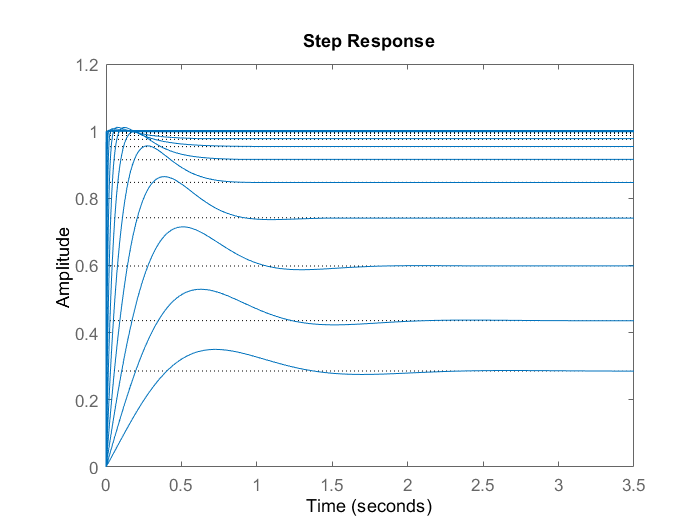

step(cltf_cascade4)

Steady-state error decreases as we increase K. This is because we are also multiplying the CLTF by K in the numerator.  

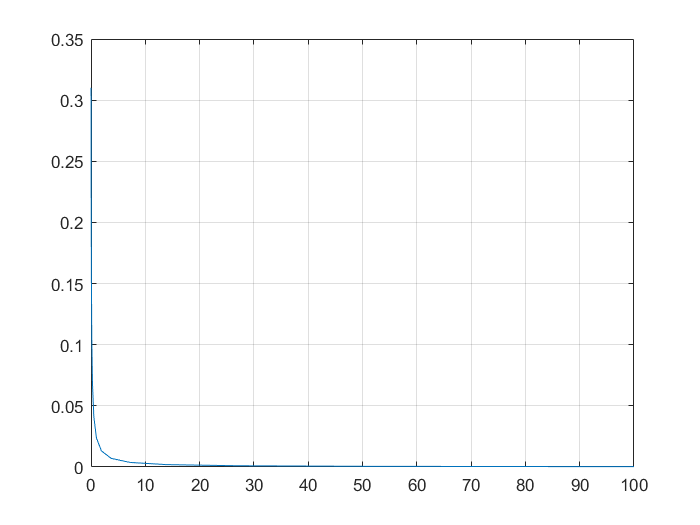

x4 = zeros(1,length(K4));
for i=1:length(K4)
    x4(:,i) = stepinfo(cltf_cascade4(:,:,:,i)).RiseTime;
end
plot(K4,x4), grid on

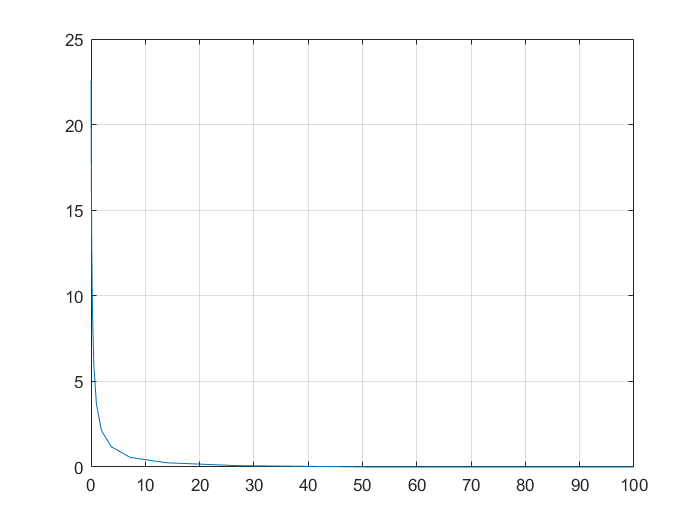


x4 = zeros(1,length(K4));
for i=1:length(K4)
    x4(:,i) = stepinfo(cltf_cascade4(:,:,:,i)).Overshoot;
end
plot(K4,x4), grid on

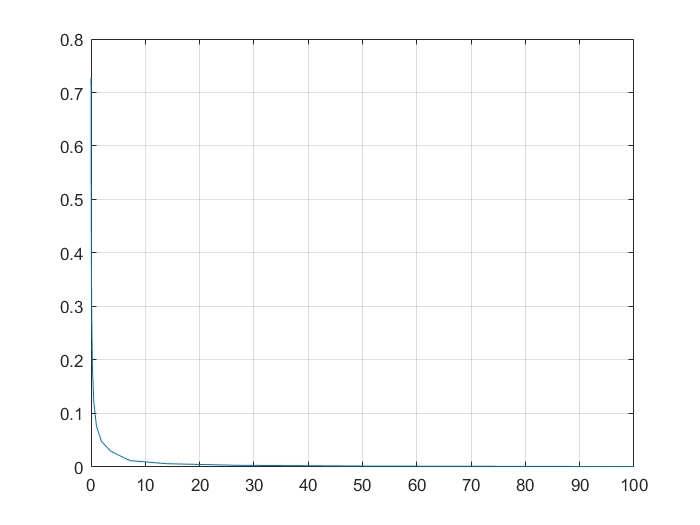


x4 = zeros(1,length(K4));
for i=1:length(K4)
    x4(:,i) = stepinfo(cltf_cascade4(:,:,:,i)).PeakTime;
end
plot(K4,x4), grid on

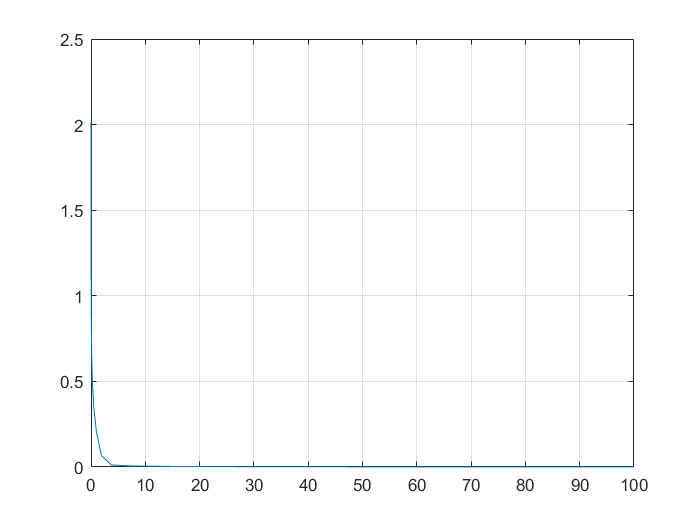

x4 = zeros(1,length(K4));
for i=1:length(K4)
    x4(:,i) = stepinfo(cltf_cascade4(:,:,:,i)).SettlingTime;
end
plot(K4,x4), grid on

We see that all four performance measures quickly decrease as we increase K - this can be explained by observing that, as we increase K, one pole moves towards the zero, and the other towards infinity. The dynamics due to the far-away pole begin to dominate, as the pole near the zero has its dynamics dulled by the zero. So we observe "faster" dynamics as expected from a far-away pole.

### Comparing performances

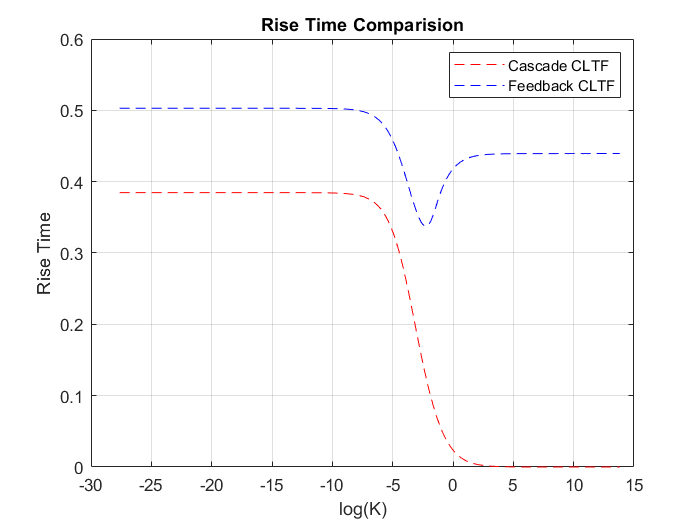


gains = logspace(-12,6,200);
oltf = tf(zeros(1,1,1,200));
for i = 1:200
    oltf(:,:,:,i) = tf([gains(i)],[1,3,10]);
end
Cascade = feedback(tf([80,80*5],1) * oltf,1);
Feedback = feedback(oltf, tf([80,80*5],1));

y1 = zeros(1,200);
for i = 1:200
    y1(:,i) = stepinfo(Cascade(:,:,:,i)).RiseTime;
end
y2 = zeros(1,200);
for i = 1:200
    y2(:,i) = stepinfo(Feedback(:,:,:,i)).RiseTime;
end
plot(log(gains),y1,'r--',log(gains),y2,'b--'), grid on
legend({'Cascade CLTF','Feedback CLTF'})
title('Rise Time Comparision')
xlabel('log(K)')
ylabel('Rise Time')

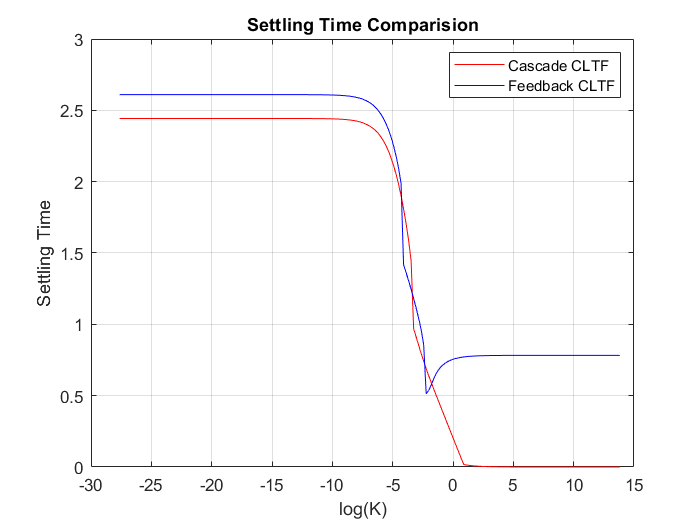

y1 = zeros(1,200);
for i = 1:200
    y1(:,i) = stepinfo(Cascade(:,:,:,i)).SettlingTime;
end
y2 = zeros(1,200);
for i = 1:200
    y2(:,i) = stepinfo(Feedback(:,:,:,i)).SettlingTime;
end
plot(log(gains),y1,'r',log(gains),y2,'b'), grid on
legend({'Cascade CLTF','Feedback CLTF'})
title('Settling Time Comparision')
xlabel('log(K)')
ylabel('Settling Time')

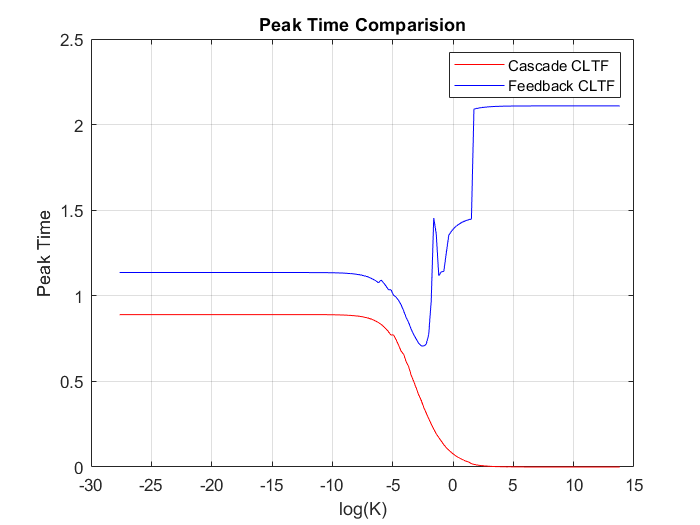


y1 = zeros(1,200);
for i = 1:200
    y1(:,i) = stepinfo(Cascade(:,:,:,i)).PeakTime;
end
y2 = zeros(1,200);
for i = 1:200
    y2(:,i) = stepinfo(Feedback(:,:,:,i)).PeakTime;
end
plot(log(gains),y1,'r',log(gains),y2,'b'), grid on
legend({'Cascade CLTF','Feedback CLTF'})
title('Peak Time Comparision')
xlabel('log(K)')
ylabel('Peak Time')

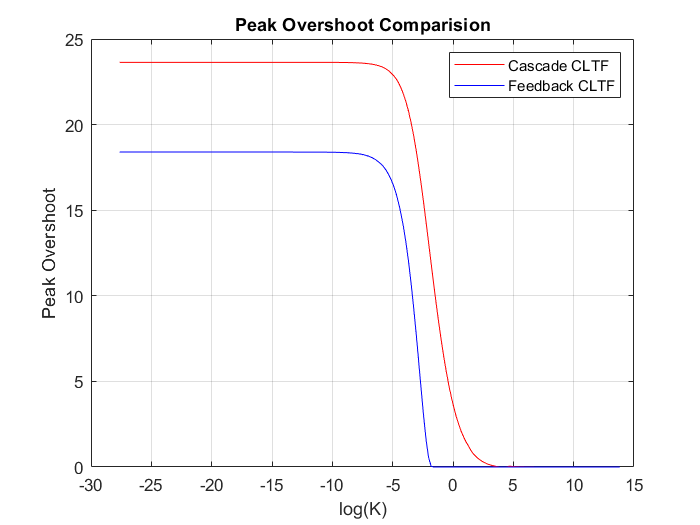


y1 = zeros(1,200);
for i = 1:200
    y1(:,i) = stepinfo(Cascade(:,:,:,i)).Overshoot;
end
y2 = zeros(1,200);
for i = 1:200
    y2(:,i) = stepinfo(Feedback(:,:,:,i)).Overshoot;
end
plot(log(gains),y1,'r',log(gains),y2,'b'), grid on
legend({'Cascade CLTF','Feedback CLTF'})
title('Peak Overshoot Comparision')
xlabel('log(K)')
ylabel('Peak Overshoot')

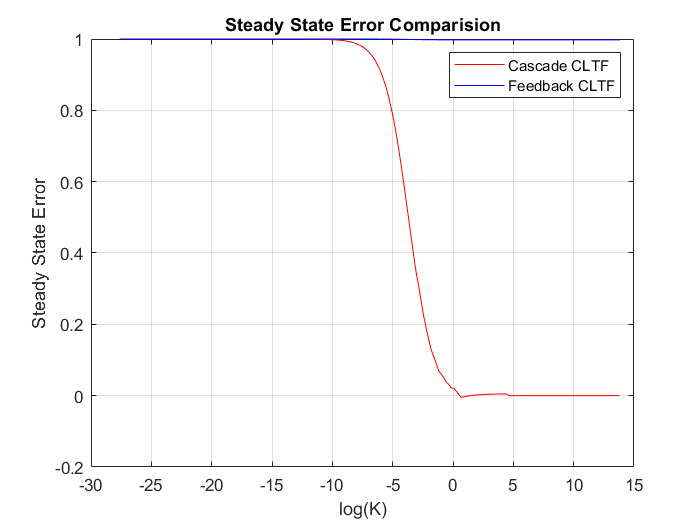


y1 = zeros(1,200);
for i = 1:200
    [y,t] = step(Cascade(:,:,:,i));
    y1(:,i) = 1-y(length(y));
end
y2 = zeros(1,200);
for i = 1:200
    [y,t] = step(Feedback(:,:,:,i));
    y2(:,i) = 1-y(length(y));
end
plot(log(gains),y1,'r',log(gains),y2,'b'), grid on
legend({'Cascade CLTF','Feedback CLTF'})
title('Steady State Error Comparision')
xlabel('log(K)')
ylabel('Steady State Error')

## Conclusions

In this experiment we have observed the difference in step responses between a PD controller connected in cascade v/s in feedback.

We learned the reason for this difference, that being the addition of a zero at s=-5 in the cascade connected CLTF. 

***It drowned out the response of the pole at -5.275, changing the dominant dynamics, and thus "speeding up" the overall step response. ***

We saw the general effect of adding a zero to the transfer function - it is the same as adding a scaled version of the derivative of the original response. We saw that as we increased the magnitude of the zero, the effect became less prominent. It was most prominent near the origin, which added a massive overshoot to the system, and near the poles, where pole-zero cancellation will occur and the order of the Transfer function would be reduced. We only analyzed the effect of zeros in the stable half of the s-plane.

We also analyzed the effect of adding a zero by way of the residue-pole-constant form of the CLTF. We saw how the pole-zero cancellation discussed above shows up in the time-domain equation y(t). It changes the coefficients of the exponential terms (i.e., it changes the residues in the partial fraction decomposition). We observed the individual contributions of the poles and how they added up to make the overall response.

Finally, we investigated the effect of variable OLTF gain on the step responses. Changing the OLTF gain changes the poles of the CLTF, thus changing the system dynamics entirely. For the TF under consideration, which was the Cascade-connected CLTF, we saw that the general effect of increasing OLTF gain was to speed up the response, since one pole quickly approached the zero at -5, allowing the other pole's fast dynamics to dominate. We plotted the variation in performance measures such as Rise Time, Overshoot, etc.  A more detailed analysis can be done through Root Locus methods, which was out of the scope of this experiment. 